# Lysosome Display and Statistical Analysis

## Set up 

setupMatGeom

Installing MatGeom Library
Adding module: geom2d               (ok)
Adding module: polygons2d           (ok)
Adding module: graphs               (ok)
Adding module: polynomialCurves2d   (ok)
Adding module: geom3d               (ok)
Adding module: meshes3d             (ok)
Adding module: utils                (ok)


### Required Variables

be sure to cd to the Lysosome Analysis folder

proj = currentProject;
cd(fullfile(proj.RootFolder,"Lysosome Analysis"))

load lysosomesVL.mat
load cellT.mat
load lysT.mat
idT = VL.Properties.UserData.idT;
idT = sortrows(idT,["Type", "Health"])

### Type I

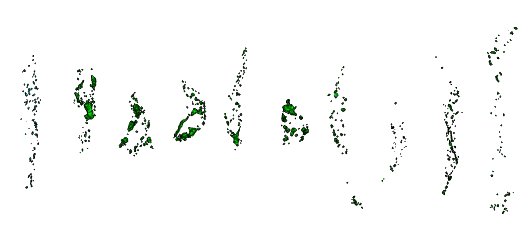

ax = plot_lys_alphaSurface(VL, idT, "I");

### Type II

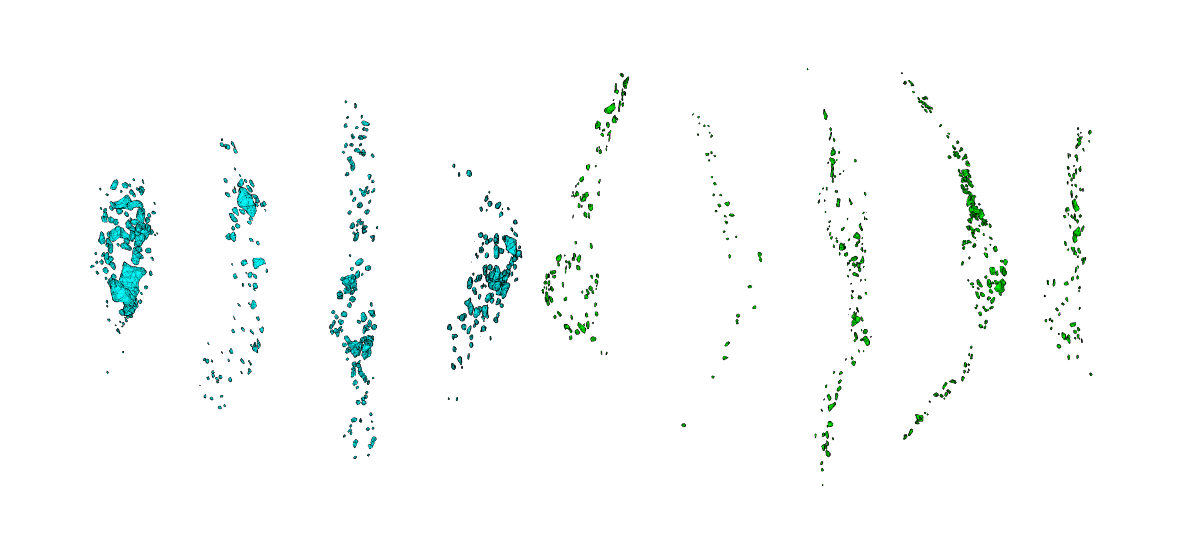

ax2 = plot_lys_alphaSurface(VL, idT, "II");

### Type III

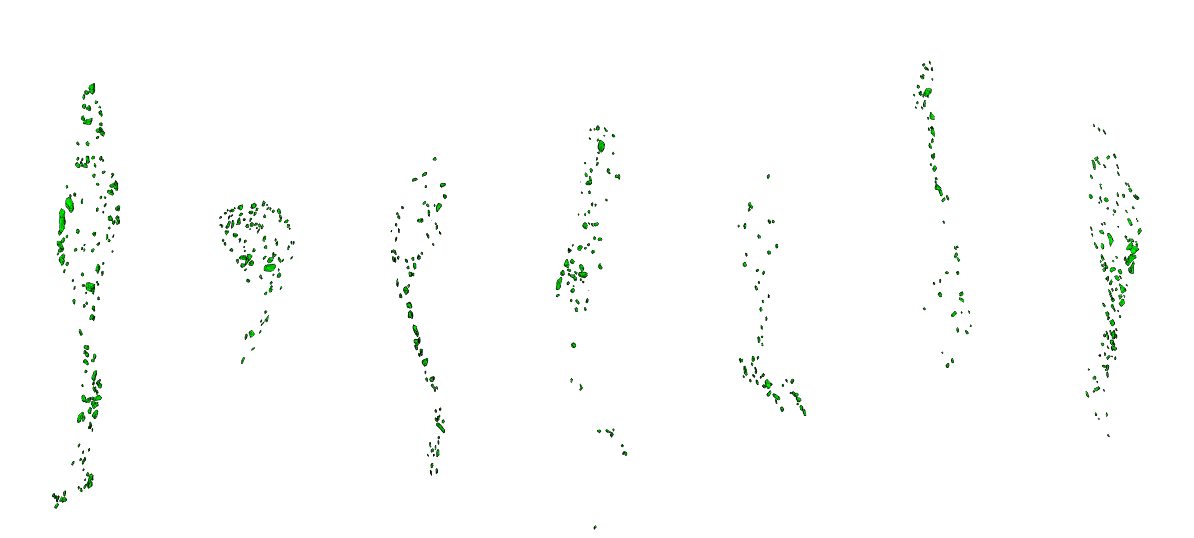

ax3 = plot_lys_alphaSurface(VL, idT, "III");

### Type 4

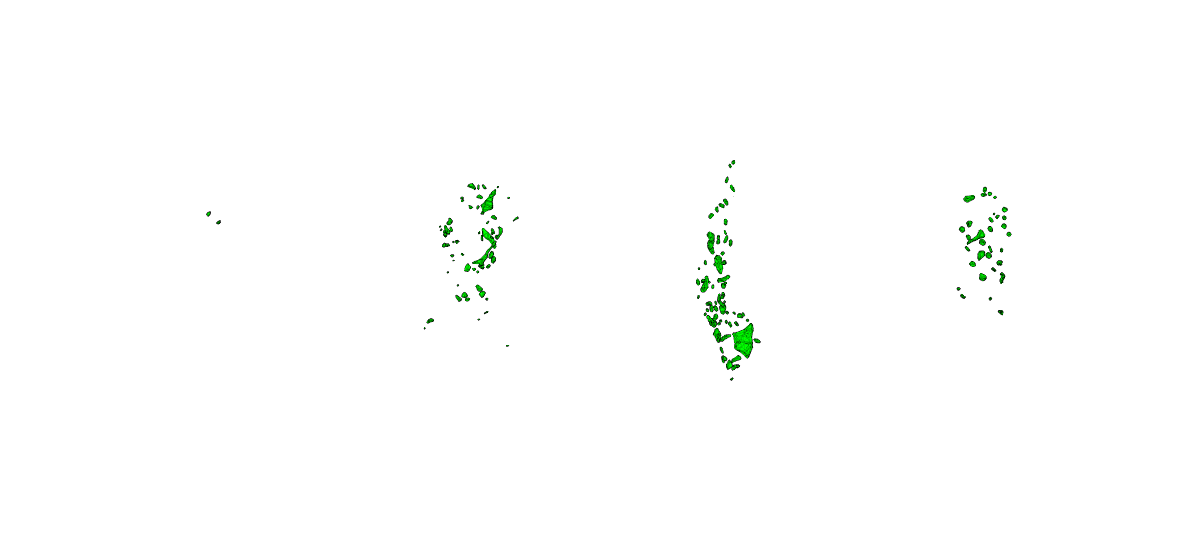

ax4 = plot_lys_alphaSurface(VL, idT, "IV");

### Type X

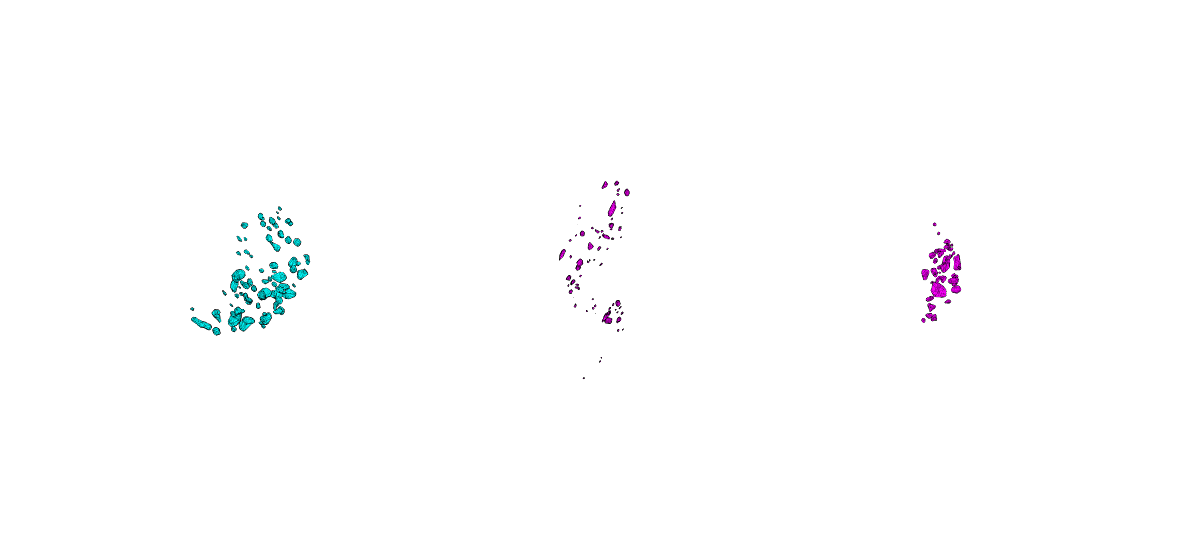

axX =   3×1 Axes array:

  Axes
  Axes
  Axes


axX = plot_lys_alphaSurface(VL,idT,"x")

## Type II Stats

 logical array simplifies analysis

la2 = lysT.Type=="II";

### Healthy II Lysosomes are much smaller than Early Dying II Lysosomes

#### Box Chart

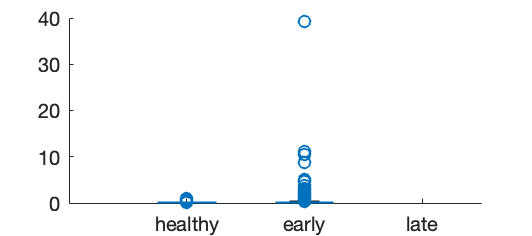

clf
x = lysT.Health(la2);
y = lysT.Volume(la2);

boxchart(x, y)

- Larger range in size

- Not normally distributed

#### Volumes not normally distributed

test for normality shows that lys II volumes are not normally distributed

[h,p] = adtest(lysT.Volume(la2))

h = logical
   1


p = 5.0000e-04

#### Group Summary Type II lysosomes

Mean and Median are significantly lower for healthy lysomes vs early dying

groupsummary(lysT(la2,:),"Health",{'mean','median', 'range', @iqr},"Volume")

ans = 2×6 table
    Health     GroupCount    mean_Volume    median_Volume    range_Volume    fun1_Volume
    _______    __________    ___________    _____________    ____________    ___________

    healthy       803         0.038098        0.0070485         1.0057        0.030617  
    early         697          0.24439         0.020161         39.143         0.11016  


- difference between mean and median shows skew in distribution of data

- Early dying cells have a much larger range in volume than the healthy cells

- Interquartile range large too

#### Healthy Lysosomes Significantly smaller

Ranksum is a Mann-Whitney U-test

x = lysT.Volume(la2 & lysT.Health == "healthy");
y = lysT.Volume(la2 & ~(lysT.Health == "healthy"));

p = ranksum(x,y)

## All Cell Types Health Comparison: 

### Late dying cells do not have the largest lysosomes 

Volume order is: late < healthy <  early

#### Late dying lysosomes larger than healthy but smaller than early dying

% lax = lysT.Type == "x";
groupsummary(lysT,"Health",{'mean','median', 'range', @iqr},"Volume")

p = 2.8158e-22

### These size differences are significant

using a kruskal wallis analysis

y = lysT.Volume;

ans = 3×6 table
    Health     GroupCount    mean_Volume    median_Volume    range_Volume    fun1_Volume
    _______    __________    ___________    _____________    ____________    ___________

    healthy       2726        0.075656        0.0085102         23.316        0.028022  
    early          914         0.21685         0.021659         39.143         0.10606  
    late           187        0.045748        0.0033834         1.7159        0.031163  


g = lysT.Health;
[p,tbl,stats] = kruskalwallis(y,g)
multcompare(stats)

## Healthy Cell comparison

Volume Order: III < II < I < IV

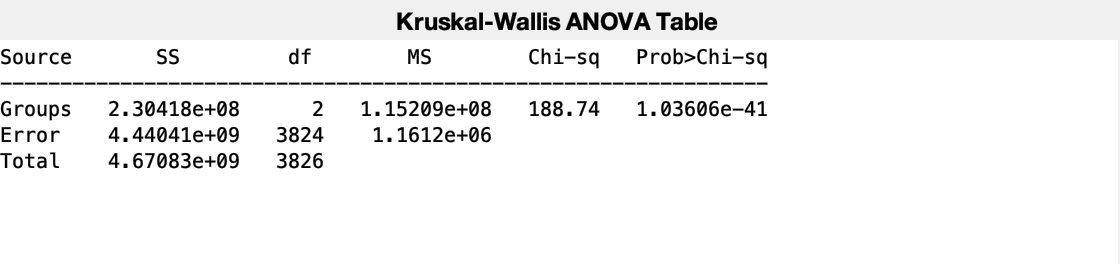

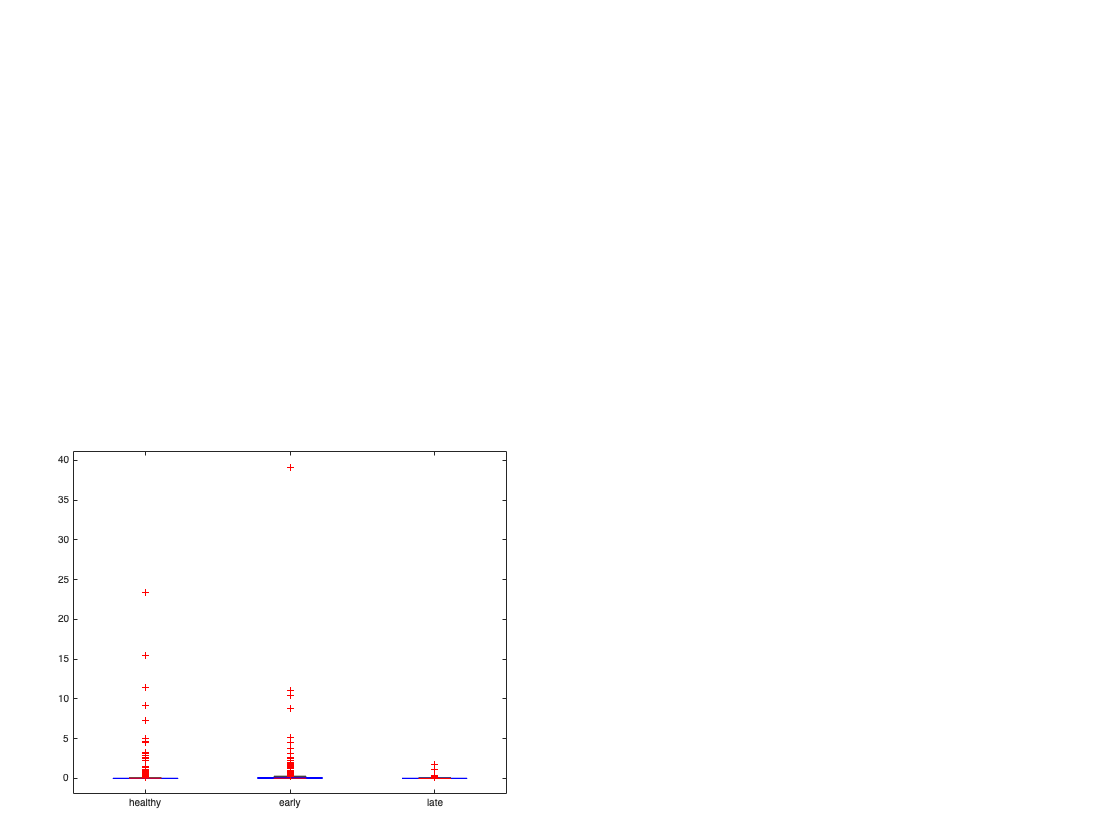

p = 1.0361e-41

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'  }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[2.3042e+08]}    {[   2]}    {[1.1521e+08]}    {[188.7411]}    {[ 1.0361e-41]}
    {'Error' }    {[4.4404e+09]}    {[3824]}    {[1.1612e+06]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[4.6708e+09]}    {[3826]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {3×1 cell}
            n: [2726 914 187]
       source: 'kruskalwallis'
    meanranks: [1.8087e+03 2.3274e+03 1.4290e+03]
         sumt: 0


lah = lysT.Health == "healthy";
statsHealth = groupsummary(lysT(lah,:),"Type",{'mean','median', 'range', @iqr},"Volume");
statsHealth = sortrows(statsHealth,"median_Volume")

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


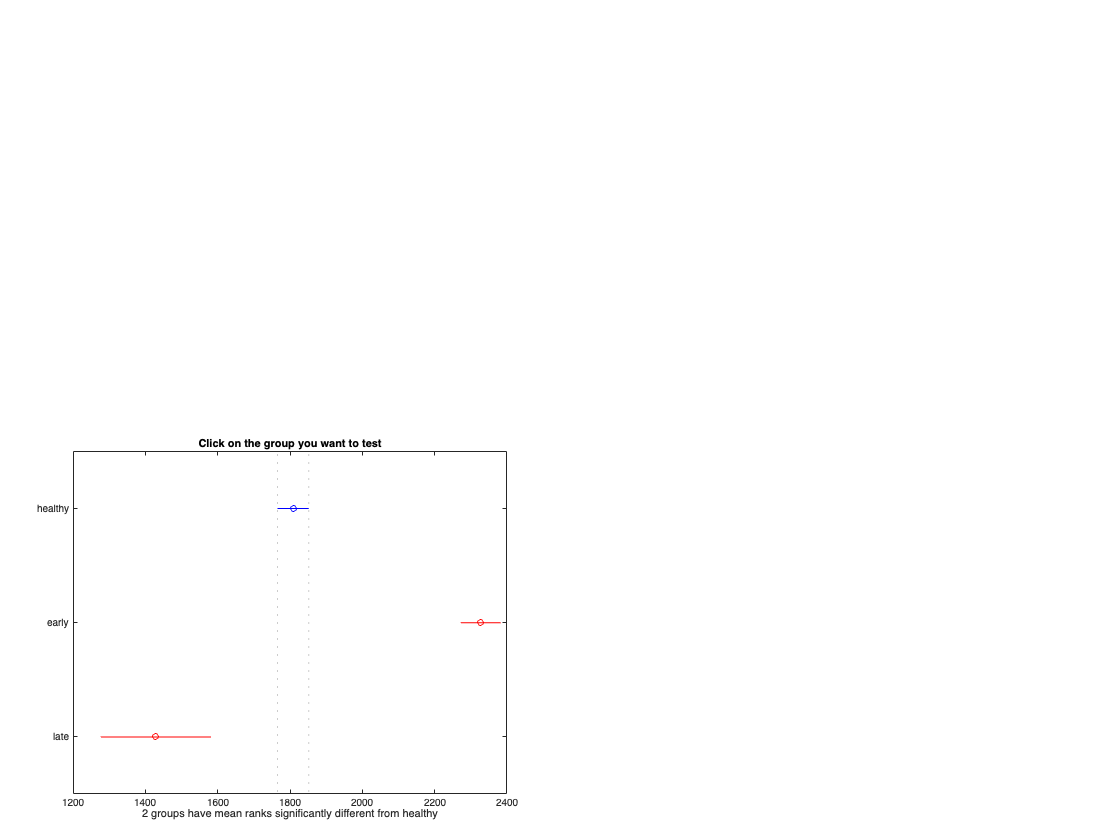

ans = 1.0e+03 *

    0.0010    0.0020   -0.6177   -0.5187   -0.4197         0
    0.0010    0.0030    0.1839    0.3797    0.5754    0.0000
    0.0020    0.0030    0.6905    0.8984    1.1062         0


y = lysT.Volume(lah);

g = lysT.Type(lah);
[p,tbl,stats] = kruskalwallis(y,g)

multcompare(stats)

## Local Functions

function ax = plot_lys_alphaSurface(VL, idT, type)


statsHealth = 4×6 table
    Type    GroupCount    mean_Volume    median_Volume    range_Volume    fun1_Volume
    ____    __________    ___________    _____________    ____________    ___________

    III        921         0.022354        0.0068473        0.65202        0.015919  
    II         803         0.038098        0.0070485         1.0057        0.030617  
    I          779          0.17998        0.0099288         23.316        0.037866  
    IV         223         0.066603         0.019371         3.0833        0.055665  


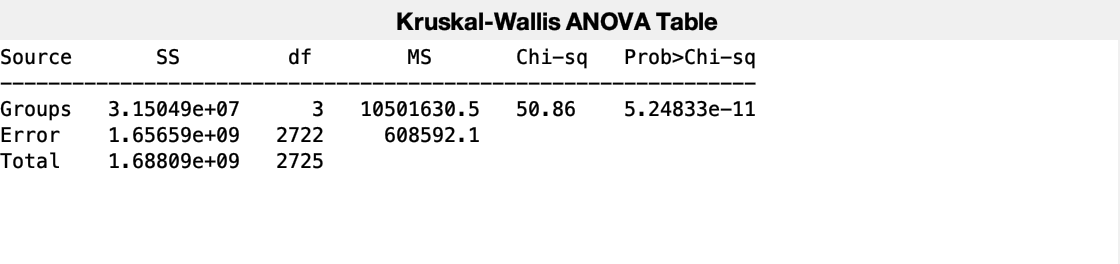

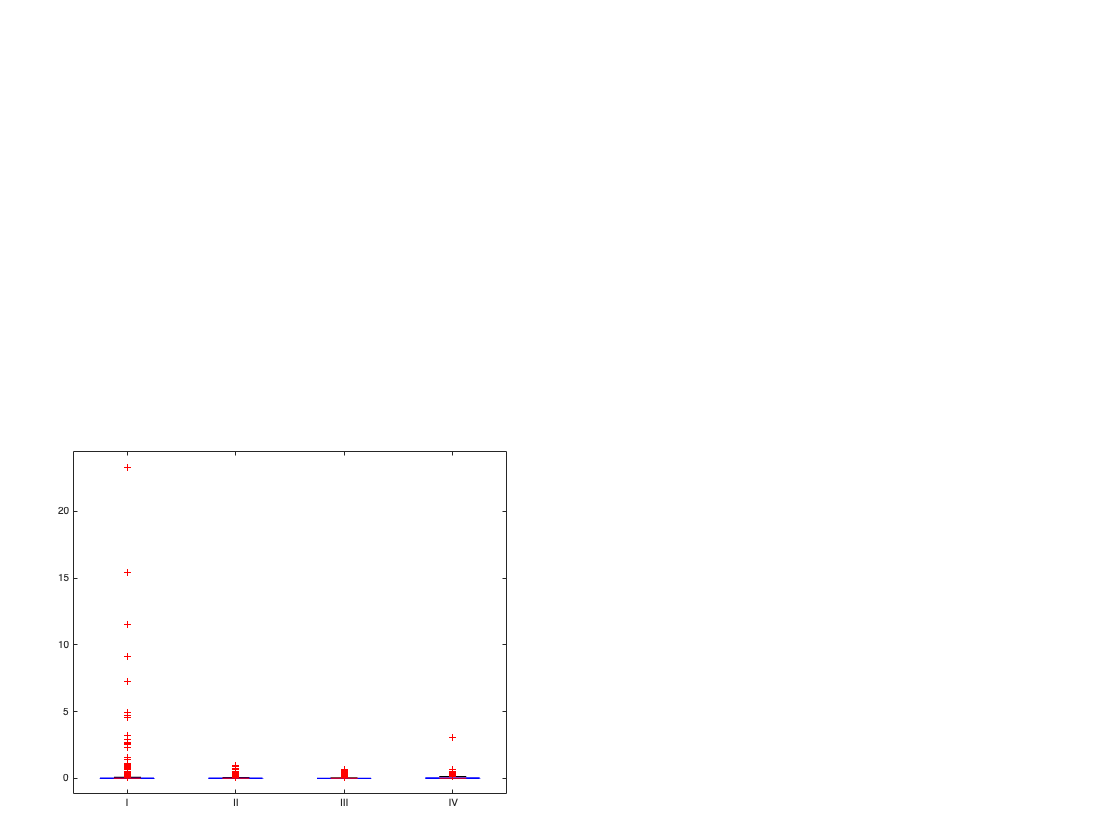

p = 5.2483e-11

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'  }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[3.1505e+07]}    {[   3]}    {[1.0502e+07]}    {[ 50.8567]}    {[ 5.2483e-11]}
    {'Error' }    {[1.6566e+09]}    {[2722]}    {[6.0859e+05]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[1.6881e+09]}    {[2725]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {4×1 cell}
            n: [779 803 921 223 0]
       source: 'kruskalwallis'
    meanranks: [1.4496e+03 1.3529e+03 1.2431e+03 1.5982e+03 NaN]
         sumt: 0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


Error using meansgraph
Wrong number of group names.

Error in multcompare>makeGraph (line 340)
hh = meansgraph(gmeans, gmeans-halfwidth, gmeans+halfwidth, ...

Error in multcompare>makeM (line 308)
    hh = makeGraph(gmeans,se,crit,gnames,mname,meandiff,control);

Error

fh = mmfig;
fh.Name = sprintf("Type %s",type); 
tiledlayout("flow","TileSpacing","none","Padding","tight");
idc = find(idT.Type==type)';

colorD = dictionary(["healthy" "early" "late"], ["g" "c" "m"]);
ax = gobjects(numel(idc),1);
i = 1;
for m=idc
    
    [~, vLys, SzLbl] = getVertsFromCellID(VL, idT.Cell(m),1); % align point clouds to axes

    PC = pointCloud(vLys);
    
    ax(i) = nexttile;
    i = i+1;

    for n=unique(SzLbl)'
    la = SzLbl == n;
    PCselect = select(PC,la);
    if isscalar(unique(PCselect.Location(:,3))) % if just one z slice
        pts = PCselect.Location;
        pts = [pts;...
            pts(:,1:2) pts(:,3)+0.08]; % duplicate points to the next slice to create cylinder
    else
        pts = PCselect.Location;
    end
    shp3d = alphaShape(pts,1); % alpha of 1 most reliable
    plot(shp3d, FaceColor=colorD(idT.Health(m)),EdgeAlpha=0.1,Tag=idT.Cell(m));
    hold on
    axis off
   
    xlim([-10 10])
    ylim([-10 10])
    zlim([-50 50])

    set(gca,CameraTarget=[0,0,0], CameraViewAngle=2)
    end

end
end